# This is the live script for ESE 6190 HW6 Explicit MPC Exercise 2

clear all
clc

## Part A: mpQP and mpLP

## dynamics rollout

u = sdpvar(2, 1);
x = sdpvar(1, 1);
x1 = 0.5*x(1) + u(1);
x2 = 0.5*x1 + u(2);

## Solve the QP

J = 0.5*(x1^2 + x2^2 + u(1)^2 + u(2)^2)

Quadratic scalar (real, homogeneous, 3 variables)
Coefficients range: 0.15625 to 1.125


C = [ 2.5 <= x1   <=5,...
      -1  <= x2   <=1,...
      -2  <= u(1) <=2,...
      -2  <= u(2) <=2];
mpQP = Opt(C, J, x, u);
solution = mpQP.solve();

mpt_plcp: 3 regions


## Plot the QP result

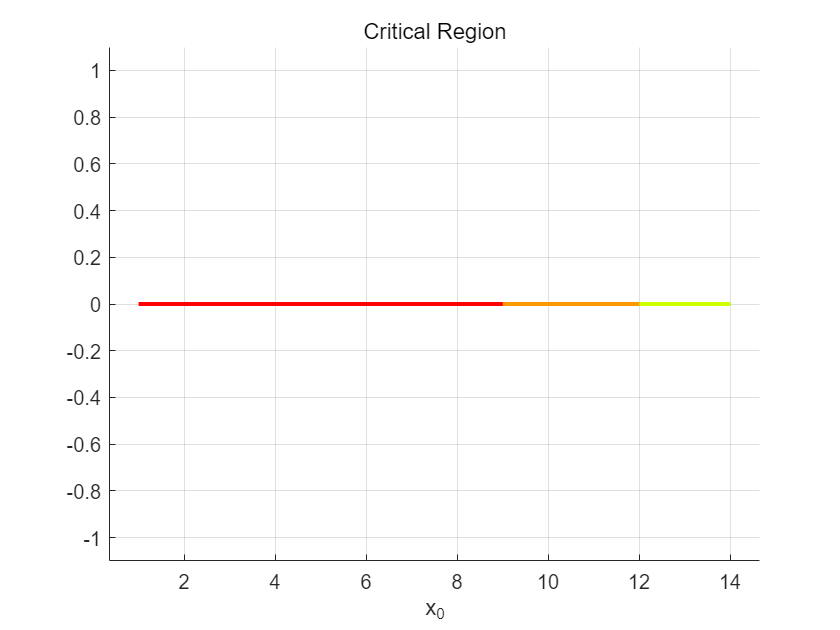

figure;
hold on
title('Critical Region')
xlabel('x_0')
solution.xopt.plot('LineWidth',2);

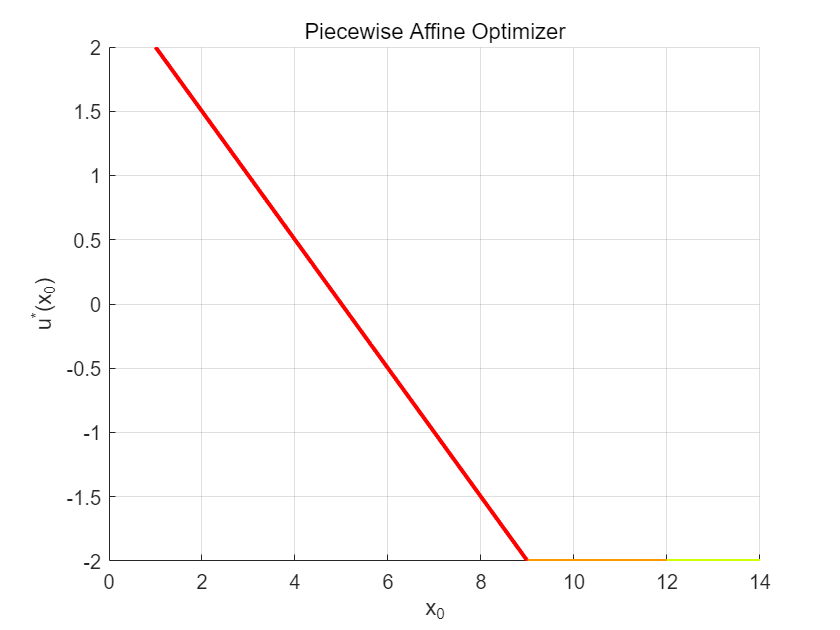

figure;
hold on
xlabel('x_0')
ylabel('u^*(x_0)')
title('Piecewise Affine Optimizer')
solution.xopt.fplot('primal','LineWidth',2);

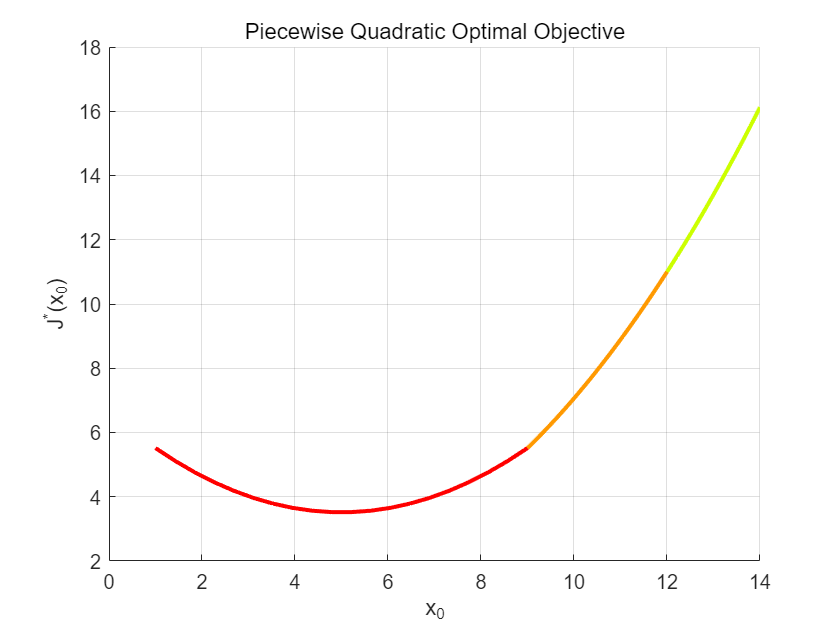

figure;
hold on
xlabel('x_0')
ylabel('J^*(x_0)')
title('Piecewise Quadratic Optimal Objective')
solution.xopt.fplot('obj','LineWidth',2);

## Solve the LP

J = abs(x1)+0.5*abs(x2)+0.5*abs(u(1))+abs(u(2));
C = [ 2.5 <= x1   <=5,...
      -1  <= x2   <=1,...
      -2  <= u(1) <=2,...
      -2  <= u(2) <=2];
mpLP = Opt(C, J, x, u);
solution = mpLP.solve();

mpt_plcp: 3 regions


## Plot the LP result

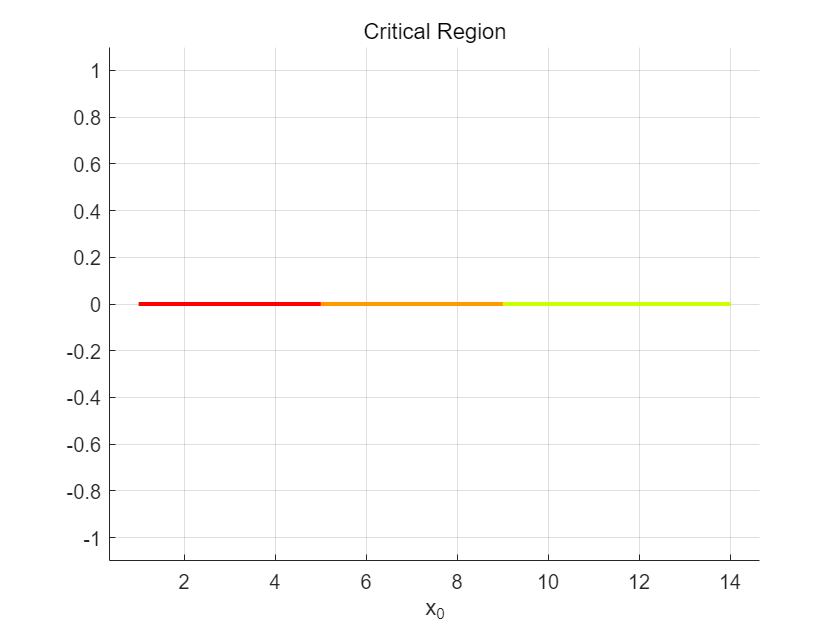

figure;
hold on
title('Critical Region')
xlabel('x_0')
solution.xopt.plot('LineWidth',2);

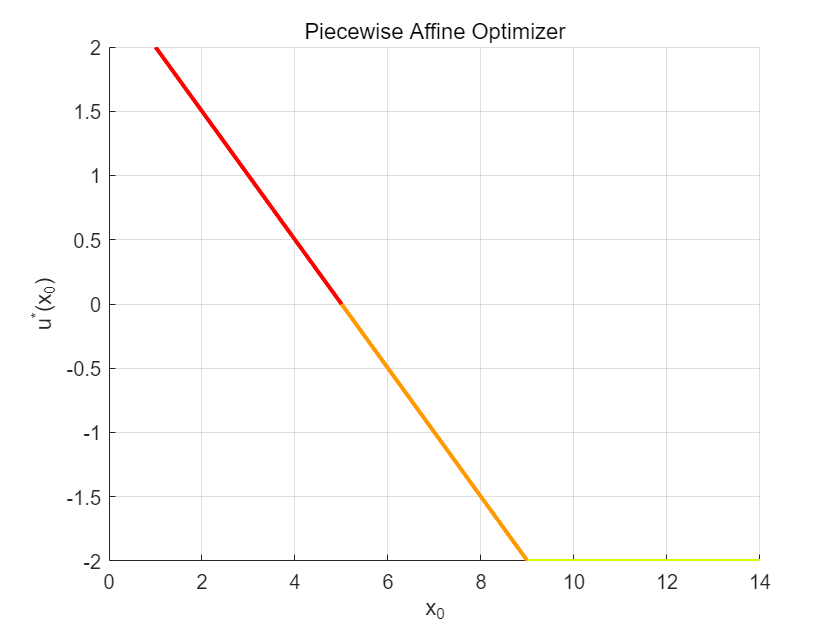

figure;
hold on
xlabel('x_0')
ylabel('u^*(x_0)')
title('Piecewise Affine Optimizer')
solution.xopt.fplot('primal','LineWidth',2);

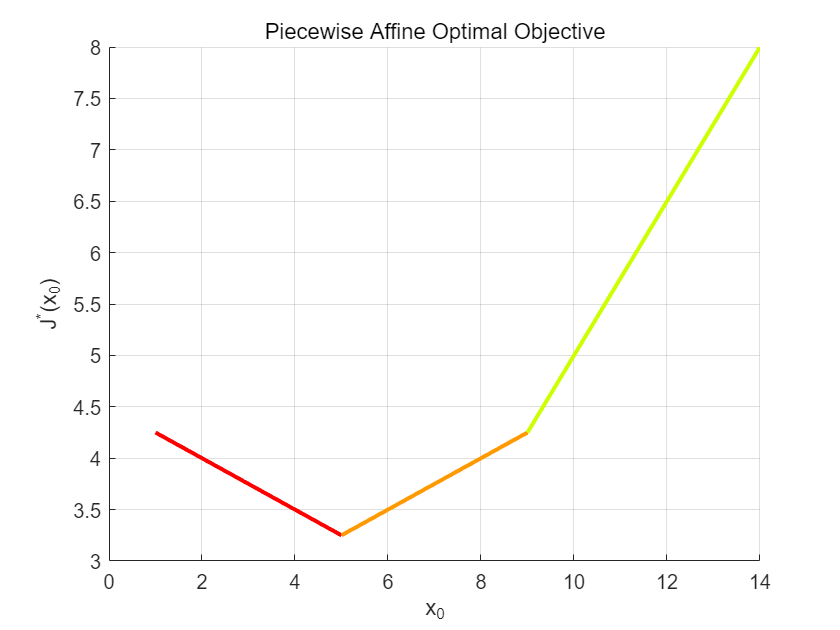

figure;
hold on
xlabel('x_0')
ylabel('J^*(x_0)')
title('Piecewise Affine Optimal Objective')
solution.xopt.fplot('obj','LineWidth',2);

## Part B: Constrained Optimal Control, Multiparametric Programming and Dynamic Programming

## dynamics, cost weight

A = [1 1;0 1];
B = [0; 1];
Q = [1 1; 0 1];
P = 0.8;
R = [1 1; 0 1];

## 1. Solve a single LP for a particular x0

N = 4;
u = sdpvar(4, 1);
stage_cost_x = 0;
stage_cost_u = 0;
x0 = [-5;0]

x0 =     -5
     0


for i= 1:N
    if i == 1
        xm = x0;
    end
    xp = A*xm + B*u(i);
    stage_cost_x = stage_cost_x + norm(Q*xm,inf);
    stage_cost_u = stage_cost_u + norm(P*u(i),inf);
    if i == 1
        x = xp;
    else
        x = [x;xp];
    end
    xm = xp;
end
J = norm(R*xp,inf) + stage_cost_x + stage_cost_u;
C = [ -10 <= x <= 10;
       -1 <= u <=1];
LP = optimize(C, J);

Optimal solution found.



u_0 = value(u)

u_0 =     1.0000
    0.3333
         0
   -0.6667


## 2. Solve the mp-LP for general controller

for N = 4:-1:1
    u = sdpvar(N, 1);
    x0 = sdpvar(2, 1);
    x = x0;
    stage_cost_x = 0;
    stage_cost_u = 0;
    for i= 1:N
        if i == 1
            xm = x0;
        end
        xp = A*xm + B*u(i);
        stage_cost_x = stage_cost_x + norm(Q*xm,inf);
        stage_cost_u = stage_cost_u + norm(P*u(i),inf);
        x = [x;xp];
        xm = xp;
    end
    J = norm(R*xp,inf) + stage_cost_x + stage_cost_u;
    C = [ -10 <= x <= 10;
           -1 <= u <=1];
    mpLP = Opt(C, J, x0, u);
    solution(5-N) = mpLP.solve();
end

mpt_plcp: 94 regions
mpt_plcp: 64 regions
mpt_plcp: 34 regions
mpt_plcp: 16 regions


u_0 = solution(1).xopt.feval([-5;0], 'primal')

u_0 =     1.0000
    0.3333
    0.0000
   -0.6667


J_0 = solution(1).xopt.feval([-5;0], 'obj')

J_0 = 15.2667

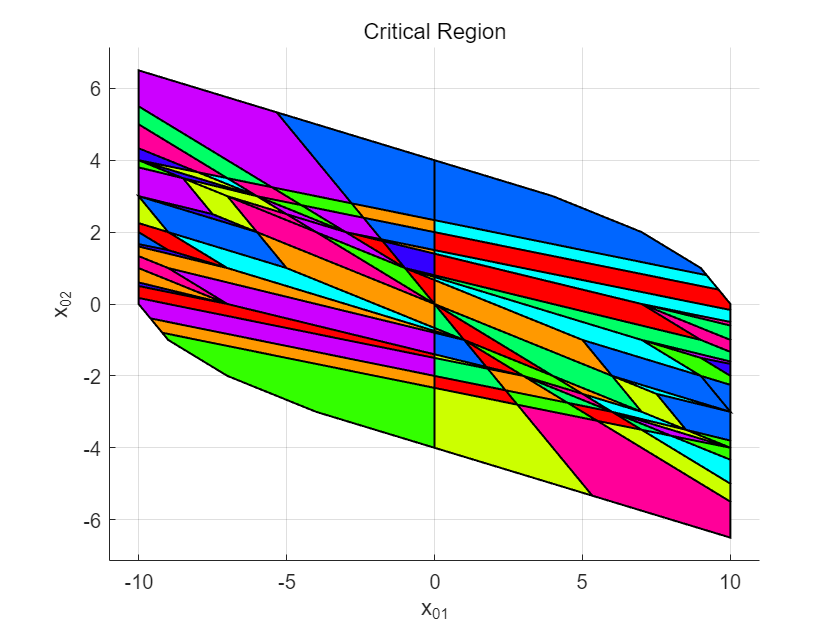

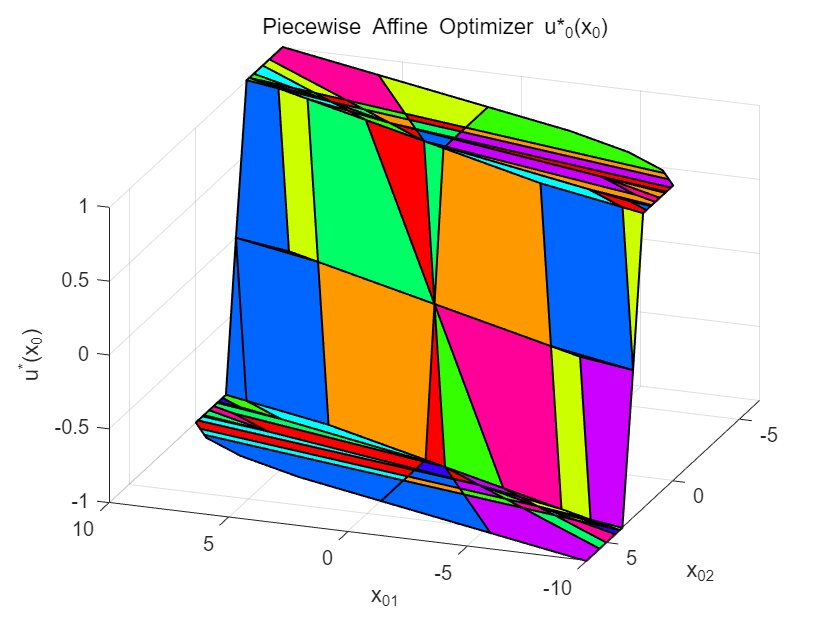

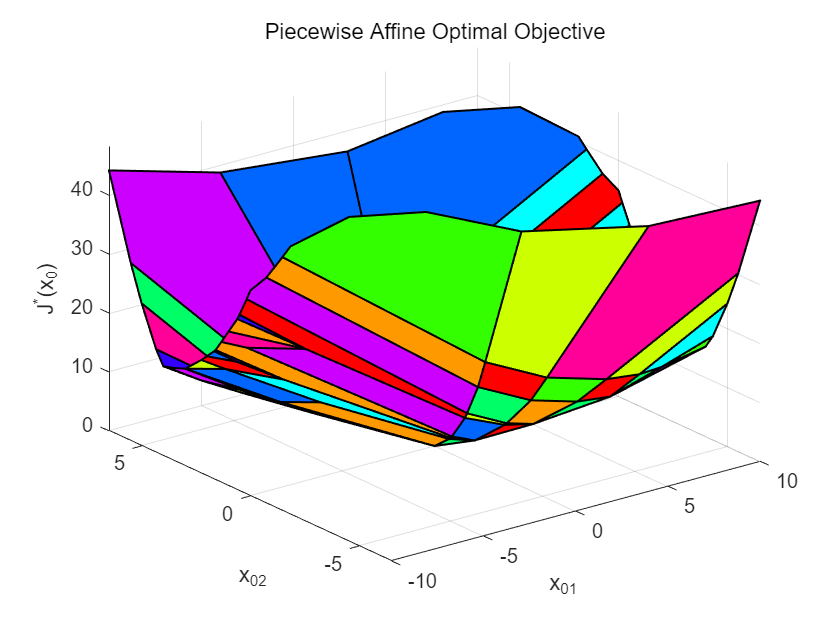

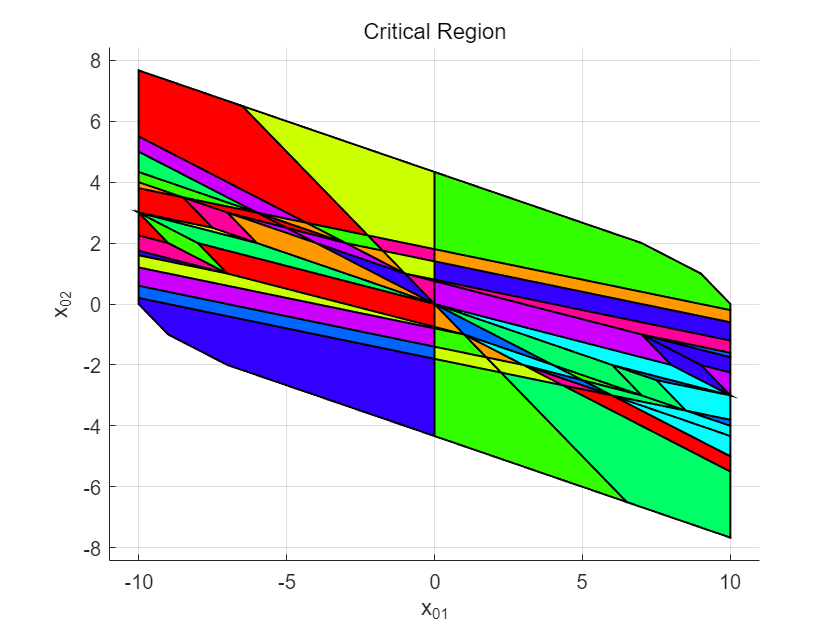

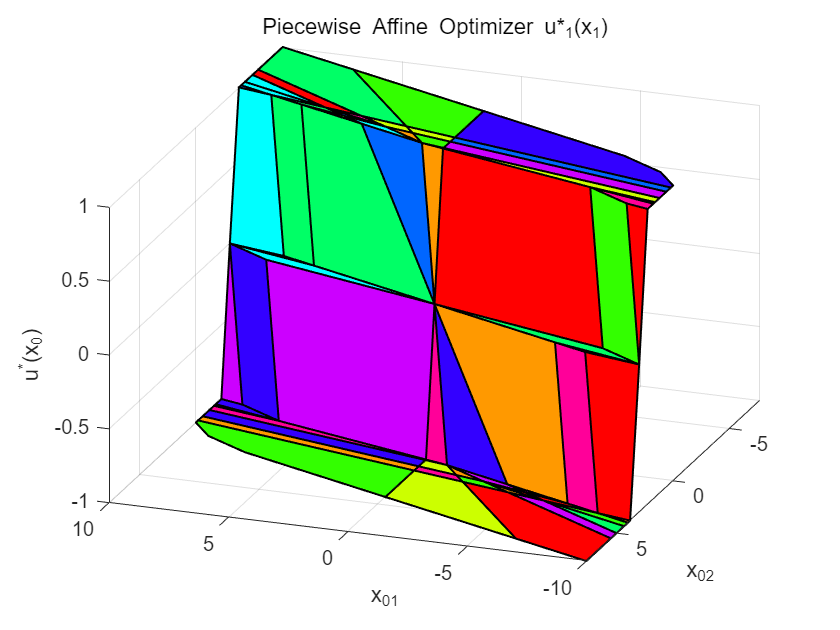

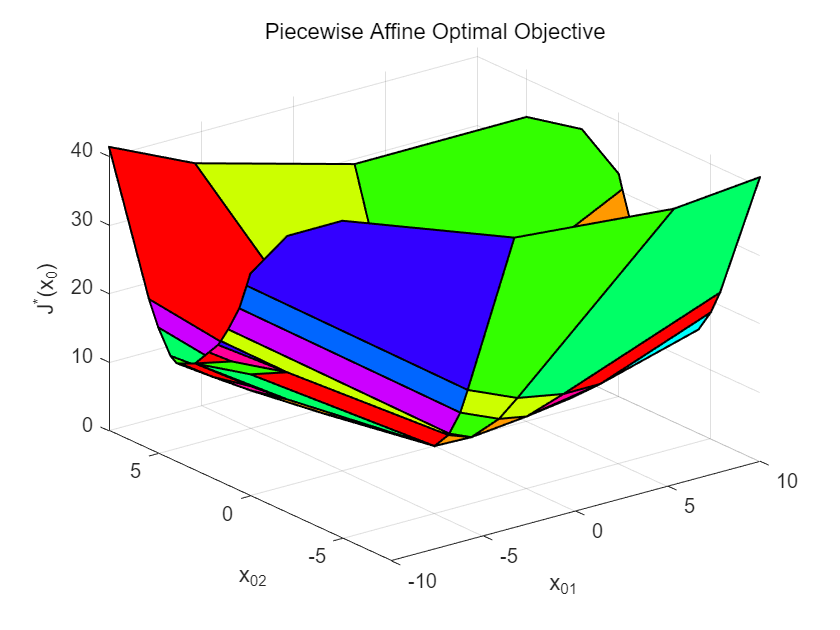

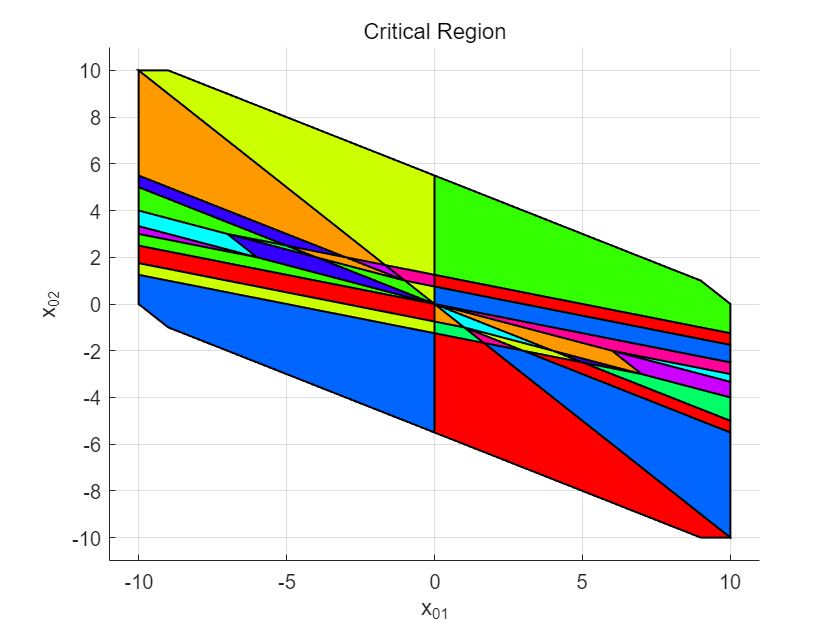

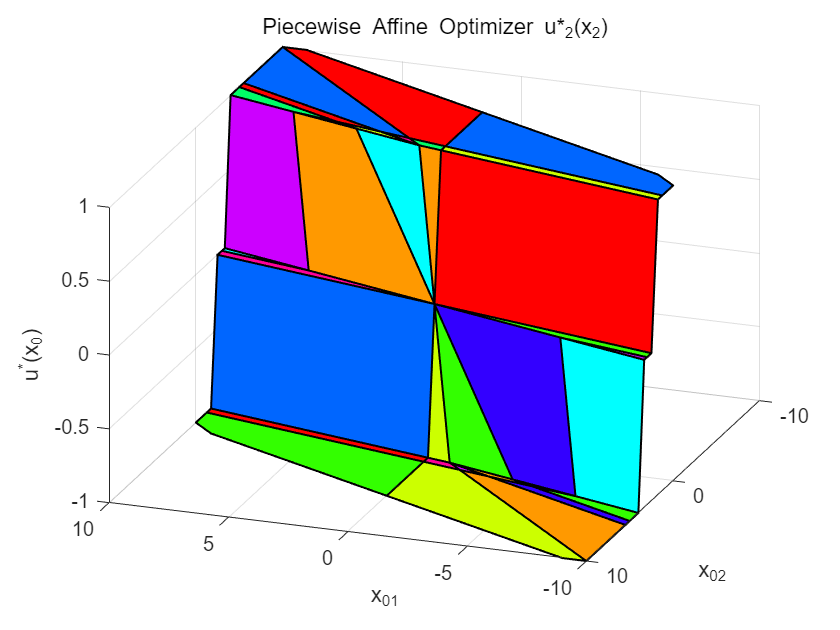

for i = 1:4
    figure;
    hold on
    title('Critical Region')
    xlabel('x_{01}')
    ylabel('x_{02}')
    solution(i).xopt.plot();
    figure;
    hold on
    xlabel('x_{01}')
    ylabel('x_{02}')
    zlabel('u^*(x_0)')
    title(['Piecewise Affine Optimizer u*_',num2str(i-1),'(x_',num2str(i-1),')'])
    solution(i).xopt.fplot('primal');
    view([-160 30]);
    figure;
    hold on
    xlabel('x_{01}')
    ylabel('x_{02}')
    zlabel('J^*(x_0)')
    title('Piecewise Affine Optimal Objective')
    solution(i).xopt.fplot('obj');
end